# Random process generation

This is a minimalist example of the generation of a random process, in one point, using the spectral method. The main function is named *randomProcess *and takes as inoput two parameters: the target power spectral density (PSD) and the associated frequency vector. In further versions, I will add additional examples with different type of power sepctral densities, esepcially PSD from vibration systems.

**References**

[1] Kaimal, J. C., & Finnigan, J. J. (1994). *Atmospheric boundary layer flows: their structure and measurement*. Oxford university press.

## Case of atmospheric  turbulence

In this section, the target spectral density used is the Kaimal turbulence model for the along-wind component [1]. 

### Generate the target PSD

clearvars;close all;clc;
fs = 8; % sampling frequency (in Hertz)
M = 15; % M is the power of 2: If M = 10, 2^M = 1024 time step
[t,f] = getSamplingPara(M,fs); % Get the frequency and time vector

Duration of target time series is 1.14 hours, i.e. 4.1e+03 sec 




% parameters used wih the Kaimal spectrum
u_star = 1; % Friction velocity
meanU = 20; % mean wind speed
z = 30; % measurement height
fr = f.*meanU/z; % reduced frequency

S = u_star.^2./f.*102.*fr./(1+33.*fr).^(5/3); % Target PSD



### Run the main function

tic
[u,~] = randomProcess(f,S);
toc

Elapsed time is 0.010130 seconds.


### Visualization of the time series

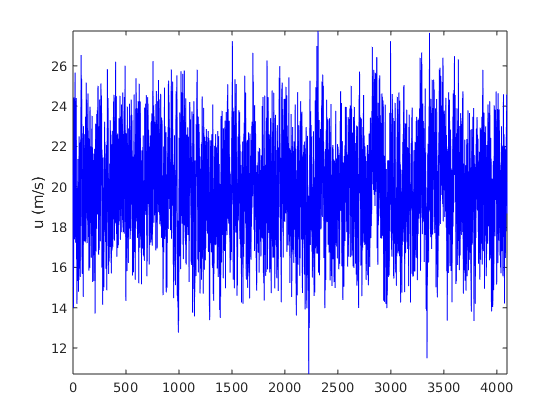

clf;close all;
figure
plot(t,u+meanU,'b')
ylabel('u (m/s)')
axis tight

Verification of the pwoer spectral densities

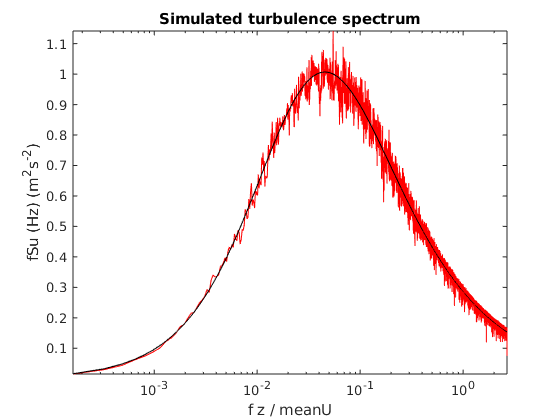

[S1,f1]=pmtm(detrend(u),10,numel(t),fs);

figure
semilogx(f1.*meanU/z,f1.*S1,'r',fr,f.*S,'k')
xlabel('f z / meanU')
ylabel('fSu (Hz) (m^2s^{-2})')
axis tight
set(gcf,'color','w')
title('Simulated turbulence spectrum')